# YBranch, TM – experimental data

## Introduction

This script analyzes experimental data to determine the insertion loss of a device under test (DUT), e.g., YBranch, using the cut-back method. The layout is several (e.g., 4) circuits each consisting of N devices in series, where N ranges from a small number (e.g., 0) to a large number.  The large number is chosen as a trade-off between the layout size and a value that gives an excess insertion loss of about 10 dB.  

For example, if the DUT is estimated to have an insertion loss of 0.3 dB, we would choose the largest value of N to be 10 dB / 0.24 dB = 42.

To find the insertion loss, we plot the measured insertion loss versus the number of DUTs in the circuit.  Then we perform a linear regression, and the slope tells us the insertion loss for one DUT.

For the case of the YBranch, the circuit consists of two YBranches facing each other. This creates an interferometer.  Assuming the waveguides are perfectly matched, the interferometer insertion loss will be only due to the excess loss of the YBranch.

The following layout implements test structures for the YBranch described in paper [http://dx.doi.org/10.1364/OE.21.001310](http://dx.doi.org/10.1364/OE.21.001310)

**Note: **Ensure you are viewing in either "Output right" or "Output inline" to see the code.

## Task

Use the Matlab code below to download, plot, and analyze the measurement data for YBranches for the TM polarization. The data is for two TM grating couplers, and several YBranches. 

The GDS file for the layout used for this experiment is [EBeam_LukasChrostowski_TM_YBranches.gds](https://s3.amazonaws.com/edx-course-phot1x-chrostowski/EBeam_LukasChrostowski_TM_YBranches.gds).

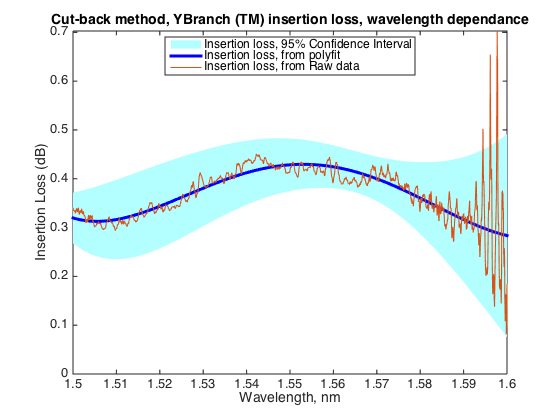

## Code

Load measurement data files

% EBeam_LukasChrostowski_TM_YBranches.gds
% https://www.dropbox.com/s/vs0hvrggbn5f9ip/EBeam_LukasChrostowski_TM_YBranches.gds?dl=1

% calculate error confidence intervals?
% check if regress function is present. This is part of the statistics toolbox.
Error_Intervals = exist('regress'); 

% Identify the name of the Device Under Test.
deviceName = 'YBranch (TM)';
% At what wavelength do you want to find out the insertion loss of the DUT
lambda0 = 1.55e-6;

% matrix of measurement data files, and # of components in each
files = { ...
    'lukasc_YBranch3_1262.mat', ...
    'lukasc_YBranch9_1261.mat', ...
    'lukasc_YBranch15_1260.mat', ...
    'lukasc_YBranch21_1263.mat' ...
    };
% number of DUTs in each circuit:
Num = [ 3, 9, 15, 21 ] * 2;
PORT=2;  % fibre measurement configuration; detector number.

% Load data from Dropbox:
if ~exist(files{1})
    disp 'Loading files from Dropbox'
    url = { ...
        'https://www.dropbox.com/s/louspt78v28x1dw/lukasc_YBranch3_1262.mat', ...
        'https://www.dropbox.com/s/cqyc233aqm8b2rc/lukasc_YBranch9_1261.mat', ...
        'https://www.dropbox.com/s/xrvtv54hmvjpfh4/lukasc_YBranch15_1260.mat', ...
        'https://www.dropbox.com/s/eiypug7qkx1p1ry/lukasc_YBranch21_1263.mat' ...
        };
    for i=1:length(files)
        a=websave(files{i},url{i},'dl', '1'); % get data from Dropbox
    end
else
    disp 'Loading files from local disk'
end

Loading files from local disk


**Plot all the raw data, and also curve-fit each to a polynomial**

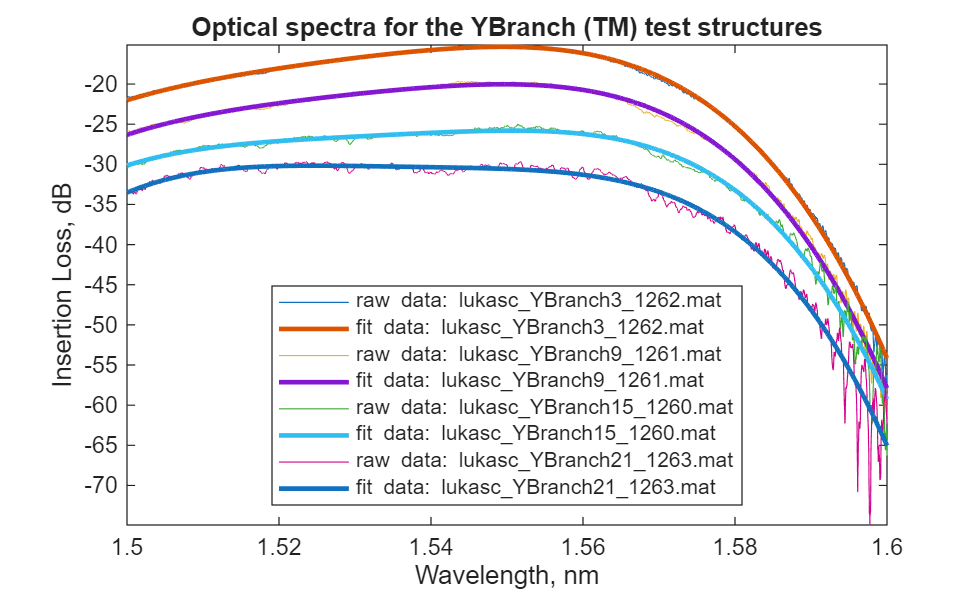

figure;
LegendText={};
for i=1:length(files)
    load(files{i});                             % Load the data
    lambda = scandata.wavelength';              % wavelength
    amplitude(:,i) = scandata.power(:,PORT);    % detector data
    plot (lambda*1e6, amplitude(:,i)); hold all;
    
    % Curve-fit data to a polynomial
    p=polyfit((lambda-mean(lambda))*1e6, amplitude(:,i), 4);
    amplitude_poly(:,i)=polyval(p,(lambda-mean(lambda))*1e6);
    plot (lambda*1e6, amplitude_poly(:,i), 'LineWidth',2);
    
    % legend entries
    LegendText(2*i-1)=cellstr(['raw data: ' strrep(files{i},'_','\_')]);
    LegendText(2*i)=cellstr(['fit data: ' strrep(files{i},'_','\_')]);
end
title (['Optical spectra for the ' deviceName ' test structures']);
xlabel ('Wavelength, nm');
ylabel ('Insertion Loss, dB');
legend (LegendText,'Location','South');
axis tight;

**Least-squares linear regression of the insertion loss values vs. number of DUTs, at lambda0, to find the slope, A(2), and y-intercept, A(1)**

The slope, A(2), is the insertion loss for one DUT

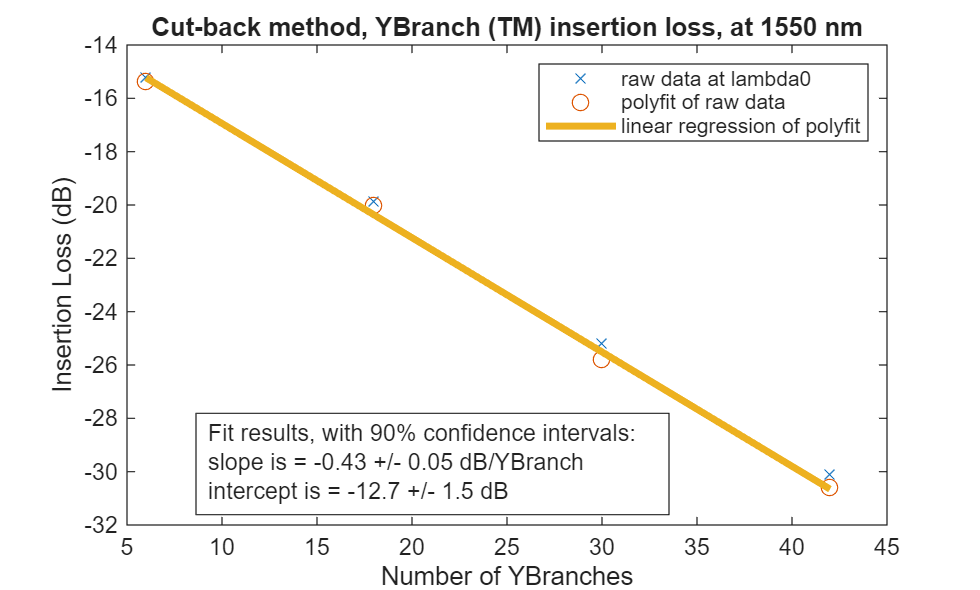

Cut-back method, YBranch (TM) insertion loss, at 1550 nm is = 0.43 +/- 0.05 dB/YBranch


[c index] = min(abs(lambda-lambda0));  % find lambda0 in lambda vector.
A = [ ones(length(Num),1) Num'] \ amplitude_poly(index,:)';
figure;
plot (Num, amplitude(index,:),'x'); hold all;
plot (Num, amplitude_poly(index,:),'o', 'MarkerSize',7);
plot (Num, A(1) + Num*A(2),'LineWidth',3)
legend ('raw data at lambda0', 'polyfit of raw data', ...
    'linear regression of polyfit');
xlabel ('Number of YBranches');
ylabel ('Insertion Loss (dB)');
title (['Cut-back method, ' deviceName ' insertion loss, at ' num2str(lambda0*1e9) ' nm'] )

% Calculate the slope error, +/- dB, with a 95% confidence interval
if Error_Intervals
    [b, bint] = regress(amplitude_poly(index,:)', [Num' ones(numel(Num),1)]);
    SlopeError95CI = diff(bint (1,:))/2;
    InterceptError95CI = diff(bint (2,:))/2;
    annotation('textbox', [.2 .2 .1 .1], 'String', ...
        {['Fit results, with 90% confidence intervals: '], ...
        ['slope is = ',num2str(A(2),'%0.2g') ' +/- ' ...
        num2str(SlopeError95CI,'%.01g') ' dB/YBranch'], ...
        ['intercept is = ',num2str(A(1),'%0.3g') ' +/- ' ...
        num2str(InterceptError95CI,'%.02g') ' dB'] ...
        });
    disp (['Cut-back method, ' deviceName ' insertion loss, at ' ...
        num2str(lambda0*1e9) ' nm is = ',num2str(-A(2),'%0.2g') ' +/- ' ...
        num2str(SlopeError95CI,'%.01g') ' dB/YBranch'])
else
    disp 'Skipping fitting error estimations'
    annotation('textbox', [.2 .2 .1 .1], 'String', ...
        {['Fit results: '], ...
        ['slope is = ',num2str(A(2),'%0.2g') ' dB/YBranch'], ...
        ['intercept is = ',num2str(A(1),'%0.3g') ' dB'] ...
        });
    disp (['Cut-back method, ' deviceName ' insertion loss, at ' ...
        num2str(lambda0*1e9) ' nm is = ',num2str(-A(2),'%0.2g') ' dB/YBranch'])
end

**Wavelength dependance of the DUT insertion loss**

perform a linear regression at each wavelength, using the raw data

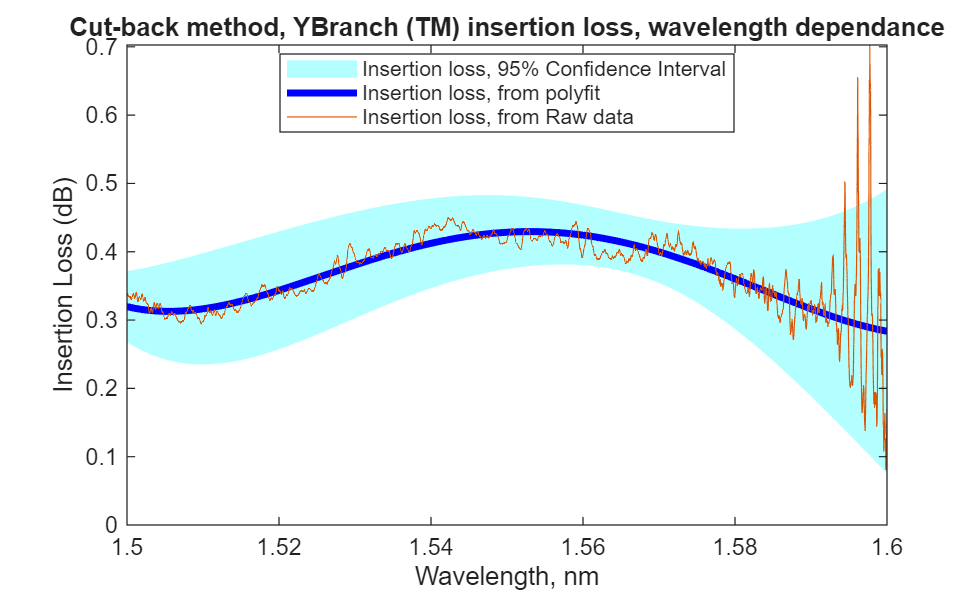

C = [ ones(length(Num),1) Num'] \ amplitude';

figure
if Error_Intervals
    % perform a linear regression at each wavelength, using the polyfit data
    slope=[]; slope_int=[];
    lambda_downsampled = lambda(1:100:end);
    amplitude_poly_downsampled = amplitude_poly (1:100:end,:);
    for i=1:length(lambda_downsampled)
        [b, bint] = regress(amplitude_poly_downsampled(i,:)', ...
            [Num' ones(numel(Num),1)]);
        slope(i)=b(1);
        slope_int(i,:)=bint(1,:);
    end
    % Plot the 95% confidence interval as a shaded region. It is based on the
    % polyfit fit results
    X=[lambda_downsampled; flip(lambda_downsampled)]*1e6;
    Y=[slope_int(:,1); flip(slope_int(:,2))];
    fill(X,-Y,[0.7 1 1],'LineStyle','none');  hold all;
    
    % plot the linear regression results from the polyfit data
    plot(lambda_downsampled*1e6, -slope', 'b', 'LineWidth',3);
    
    % plot the linear regression results from the raw data
    plot(lambda*1e6, -[C(2,:)']); hold all;
    legend ( 'Insertion loss, 95% Confidence Interval', ...
        'Insertion loss, from polyfit', ...
        'Insertion loss, from Raw data', ...
        'Location','Best' )
else
    % perform a linear regression at each wavelength, using the polyfit data
    D = [ ones(length(Num),1) Num'] \ amplitude_poly';
    plot(lambda*1e6, -[D(2,:)' C(2,:)']); hold all;
    legend ( 'Insertion loss, from polyfit', ...
        'Insertion loss, from Raw data', ...
        'Location','Best' )
end
axis tight; yl=ylim;
ylim ([0, yl(2)]);
title (['Cut-back method, ' deviceName ...
    ' insertion loss, wavelength dependance'] )
ylabel ('Insertion Loss (dB)');
xlabel ('Wavelength, nm');